close all; clear; clc;

# FRv1 10 min endurance

**file name**: FRv1_TM15d20180824.mlx

**keywords:** endurance test, fixed rate, primary test

**date of test:** 20180824

**file created by:** 20180830, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** The purpose of this test is to analyze a 10 min endurance test on on 12 volt, 75 mAh battery

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
%p = 0.00228519349876825;                  %[slugs/ft^3]
p = 0.002377;
% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('FRv1_TM15d.mat');
time = FRv1_TM15d(:,1);                       % [sec]
PWM = FRv1_TM15d(:,2);                        % [micro sec]
Q = FRv1_TM15d(:,4);                          % [ft.lbf]
T = FRv1_TM15d(:,5);                          % [lbf]
Input_V = FRv1_TM15d(:,6);                    % [Volts]
Input_A = FRv1_TM15d(:,7);                    % [Amps]
rot_speed_rpm = FRv1_TM15d(:,8);              % [RPM]
% convert to rad for calculation purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = FRv1_TM15d(:,9);                     % [Watts]
P_out_W = FRv1_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = FRv1_TM15d(:,11);                 % [%]
Prop_Eff = FRv1_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = FRv1_TM15d(:,13);               % [lbf/Watts]  
ESC_Temp = FRv1_TM15d(:,14);                  % [F]
Motor_Temp = FRv1_TM15d(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

**Convert the following lines to code if this is a Settling Time script. Delete if not applicable**

Settling_time = FRv1_TM15d(:,17); % [s]

Max_Acc = FRv1_TM15d(:,18);      % [RPM]

## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

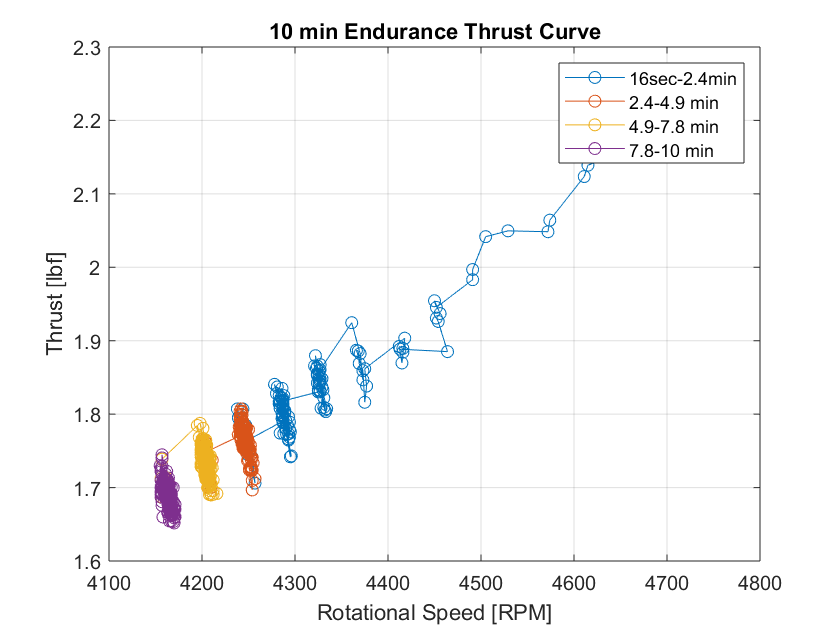

figure(1)
plot(rot_speed_rpm(22:150), T(22:150), 'o-', rot_speed_rpm(150:300), T(150:300), 'o-', rot_speed_rpm(300:475), T(300:475), 'o-', rot_speed_rpm(475:615), T(475:615), 'o-'); 
title('10 min Endurance Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');
legend('16sec-2.4min', '2.4-4.9 min', '4.9-7.8 min', '7.8-10 min' );

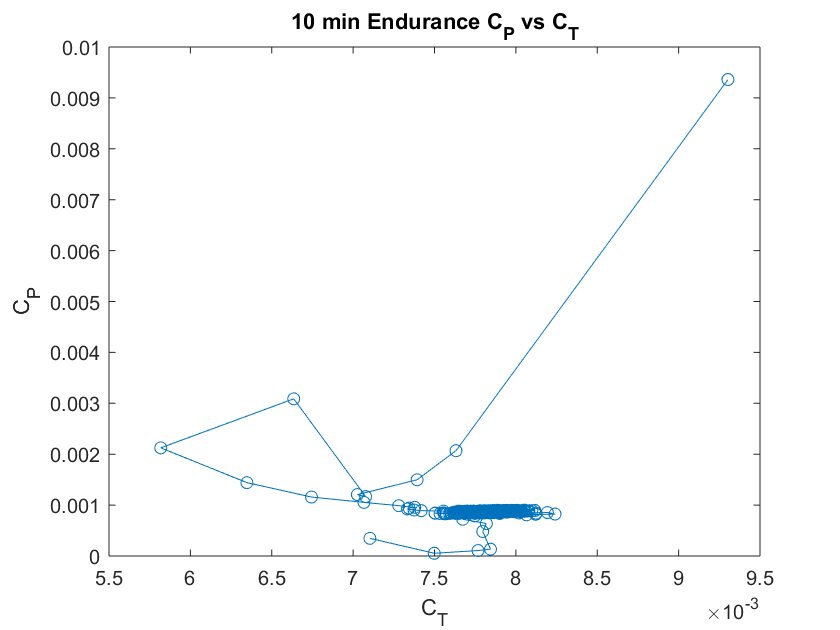


figure(2)
plot(C_T, C_P,'o-');
title('10 min Endurance C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

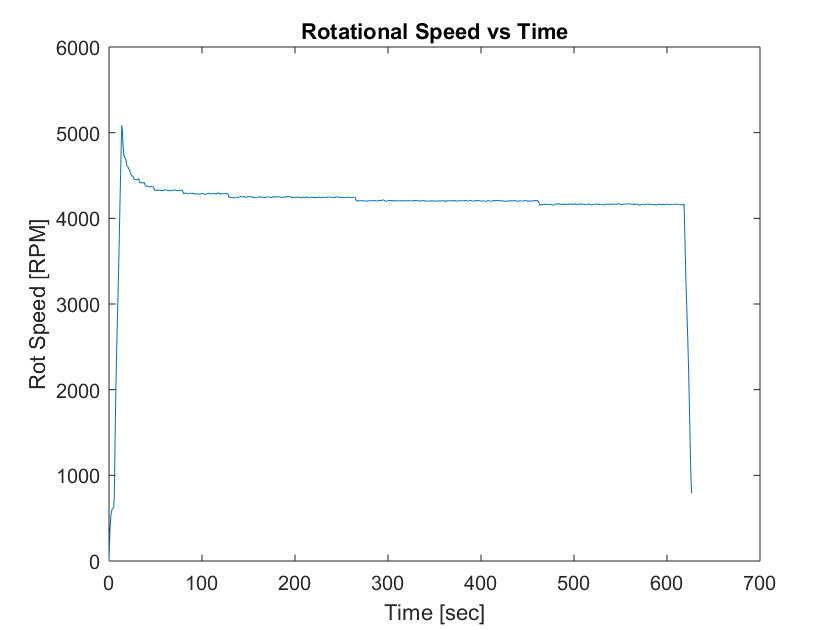


figure(3)
plot(time, rot_speed_rpm); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

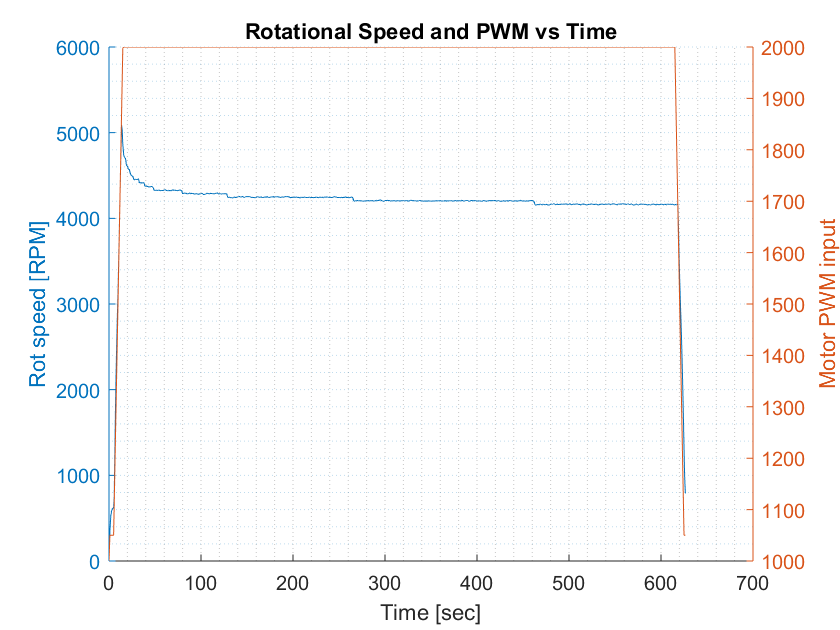


figure(4)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

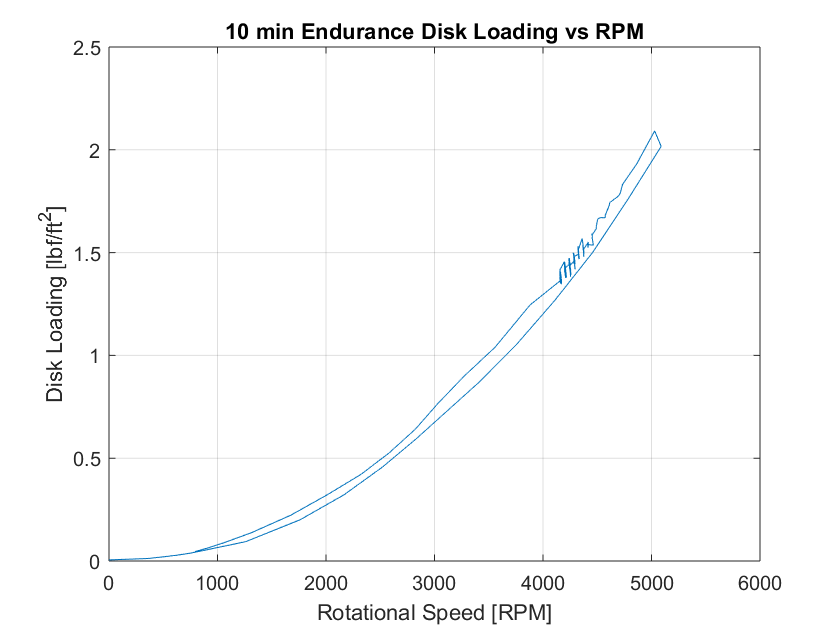


figure(5)
plot(rot_speed_rpm, disk_loading); title('10 min Endurance Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

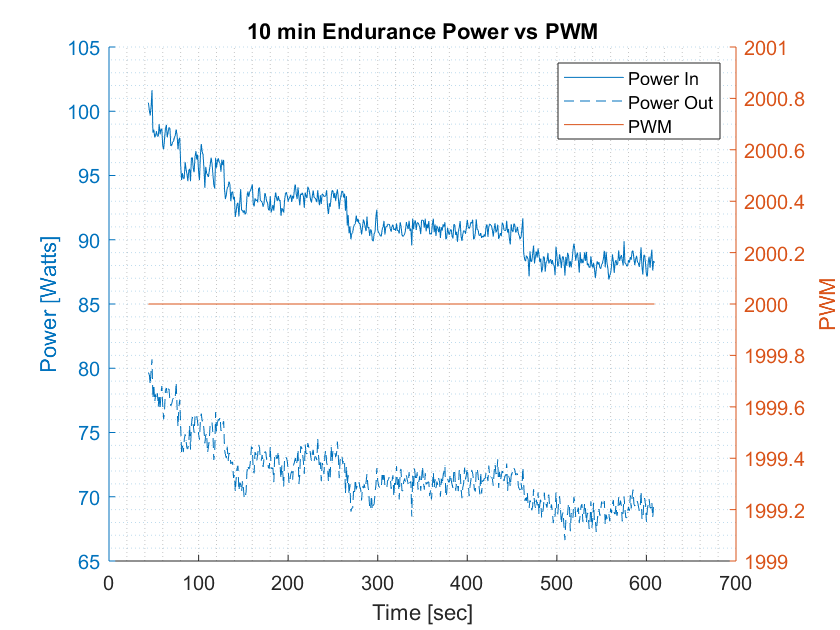


figure(6)
hold on
yyaxis left
plot(time(50:615),P_in_W(50:615), time(50:615), P_out_W(50:615));
ylabel('Power [Watts]');
legend('Power In', 'Power Out')
yyaxis right
plot(time(50:615), PWM(50:615), 'DisplayName','PWM');
ylabel('PWM');
title('10 min Endurance Power vs PWM');
xlabel('Time [sec]');
grid('minor');
hold off

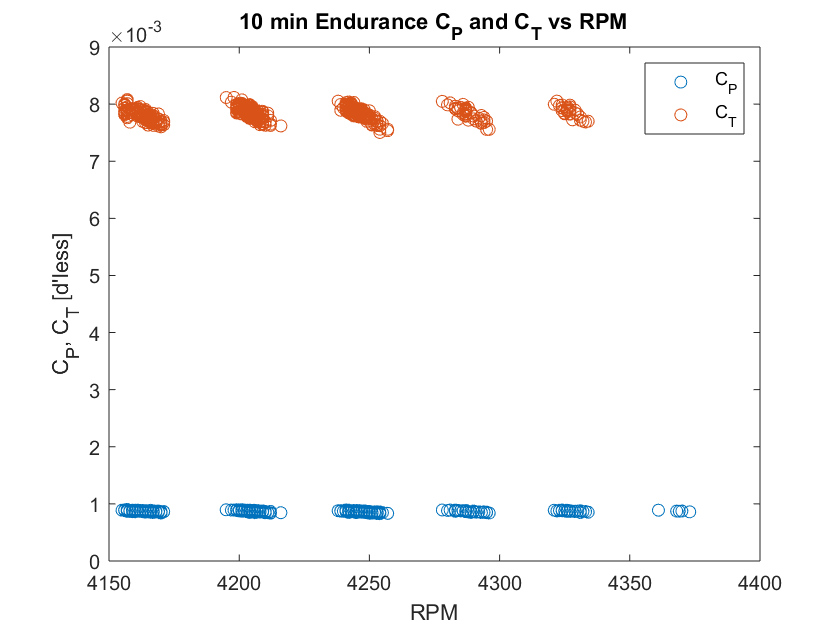


figure(7)
plot(rot_speed_rpm(50:615), C_P(50:615), 'o', rot_speed_rpm(50:615), C_T(50:615), 'o');
title('10 min Endurance C_P and C_T vs RPM'); legend('C_P', 'C_T');
xlabel('RPM'); ylabel("C_P, C_T [d'less]")

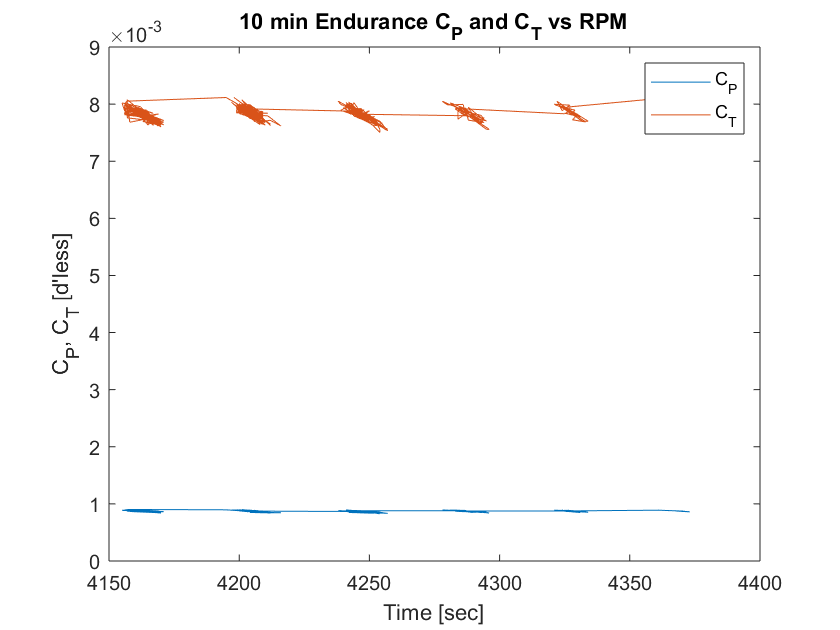




figure(8)
plot(rot_speed_rpm(50:615), C_P(50:615), rot_speed_rpm(50:615), C_T(50:615));
title('10 min Endurance C_P and C_T vs RPM'); legend('C_P', 'C_T');
xlabel('Time [sec]'); ylabel("C_P, C_T [d'less]")

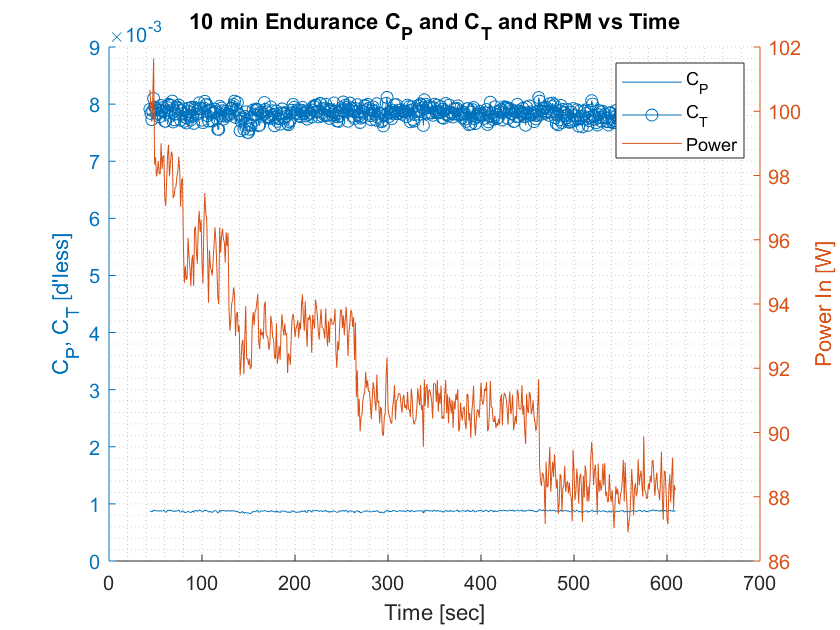



figure(9)
hold on
yyaxis left
plot(time(50:615),C_P(50:615), time(50:615), C_T(50:615), 'o-');
ylabel("C_P, C_T [d'less]");
legend('C_P', 'C_T')
yyaxis right
plot(time(50:615), P_in_W(50:615), 'DisplayName','Power');
ylabel('Power In [W]');
title('10 min Endurance C_P and C_T and RPM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

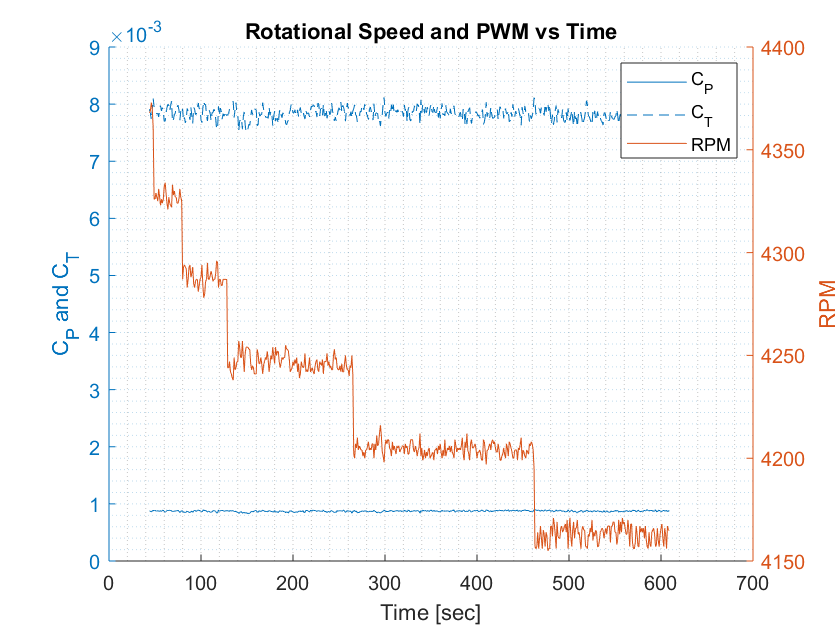


figure(10)
hold on
yyaxis left
plot(time(50:615), C_P(50:615), time(50:615), C_T(50:615));
ylabel('C_P and C_T');
legend('C_P', 'C_T');
yyaxis right
plot(time(50:615), rot_speed_rpm(50:615), 'DisplayName','RPM');
ylabel('RPM');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

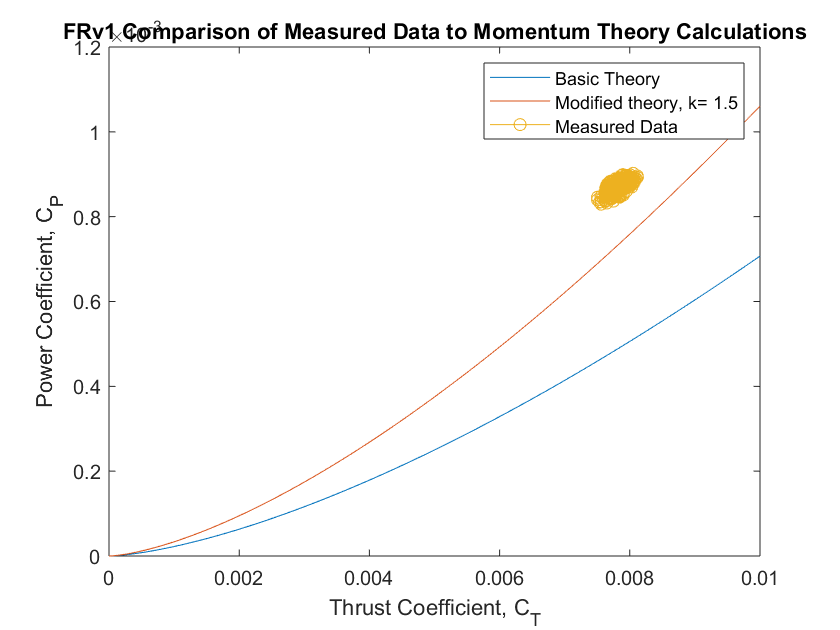

k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(11)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T(50:615), C_P(50:615), 'o-');
title('FRv1 Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data');

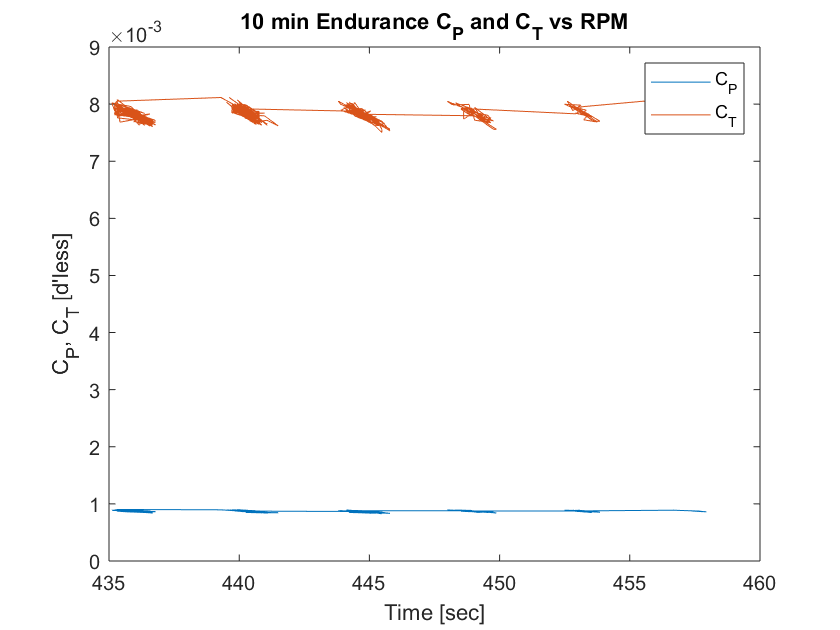







figure(12)
plot(rot_speed_rad(50:615), C_P(50:615), rot_speed_rad(50:615), C_T(50:615));
title('10 min Endurance C_P and C_T vs RPM'); legend('C_P', 'C_T');
xlabel('Time [sec]'); ylabel("C_P, C_T [d'less]")